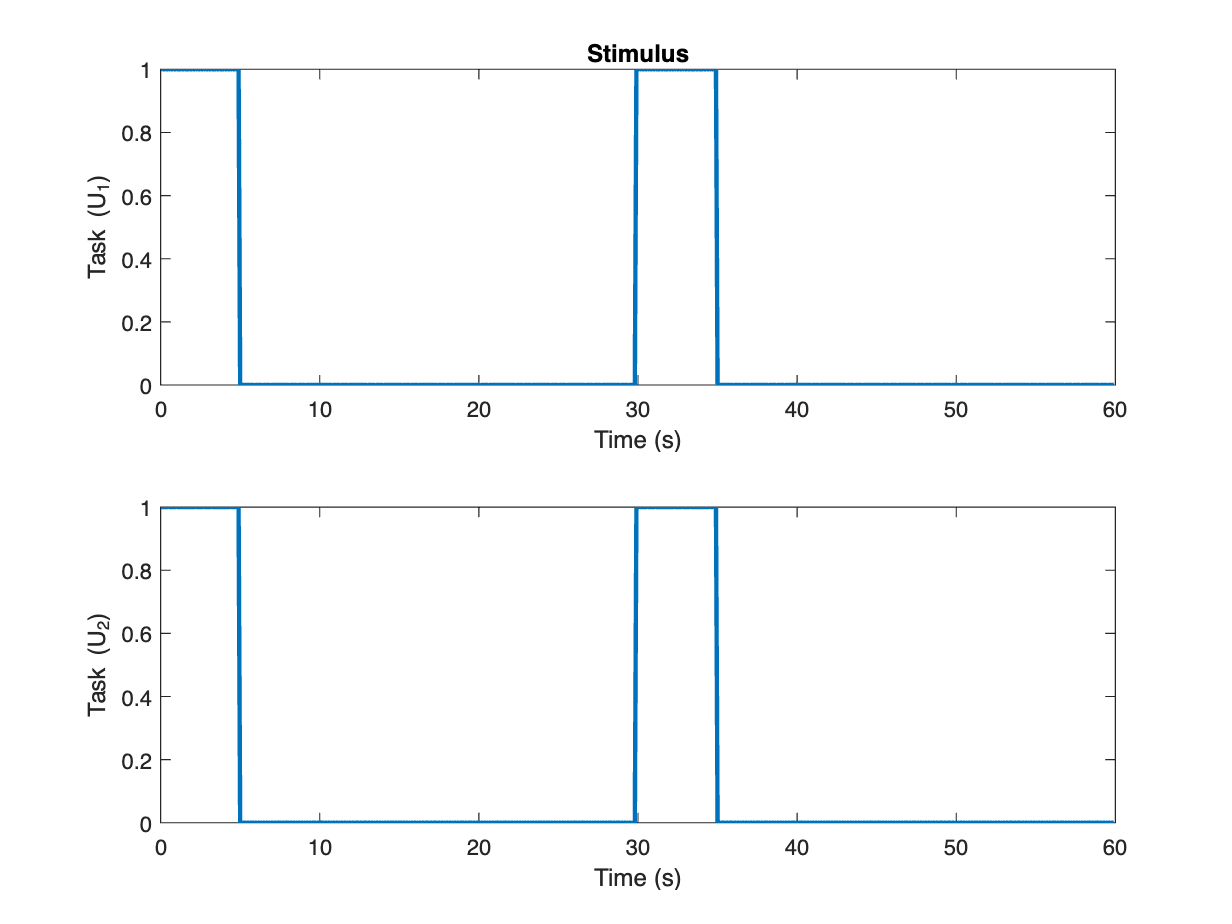

%CLEANING SPACE
close all;
clear;

%Latent connectivity. Square matrix. Sized <nRegions x nRegions>
A = [-0.16 -0.49;
     -0.02 -0.33]; 
NRegions = size(A, 1);
%Induced connectivity. Square matrix. Sized <nRegions x nRegions x nStimulus>
%B2 = [-0.02 -1; 0 -1.31]; %There must be a B per stimulus
B2 = [-0.02 -0.77; 
      0.33 -1.31]; %There must be a B per stimulus

B1 = [0 0; 0 0];
B(:,:,1) = B1;
B(:,:,2) = B2;
% Extrinsic influences of inputs on neuronal activity.
C = [0.08 0; 0.06 0];
freq = 10;

step = 1/freq;
%%
%Stimulus train
[U_stimulus, timestamps] = BilinearModel_StimulusTrainGenerator(freq, 5, 25, 2); 
%%
%Neurodynamics
[Z] = BilinearModel_Neurodynamics_Z(A,B,C, U_stimulus, step);
%%
%HEMODYNAMICS
%P_SD = [[0.0775;-0.0087] [-0.1066;0.0299] [0.0440;-0.0129] [0.8043;-0.7577]]; 
%Based on SPM
P_SD = [[0;0.05] [0;0.05] [0;0.05] [0;1]];
[qj,pj] = BilinearModel_Hemodynamics_Naive_v2(Z, U_stimulus, P_SD, A, step);


figure;
subplot(211);
plot(timestamps,U_stimulus(1,:),'LineWidth',2);
title('Stimulus');
xlabel('Time (s)');
ylabel('Task (U_{1})');
hold on;    
subplot(212);
plot(timestamps,U_stimulus(2,:),'LineWidth',2);
xlabel('Time (s)');
ylabel('Task (U_{2})');

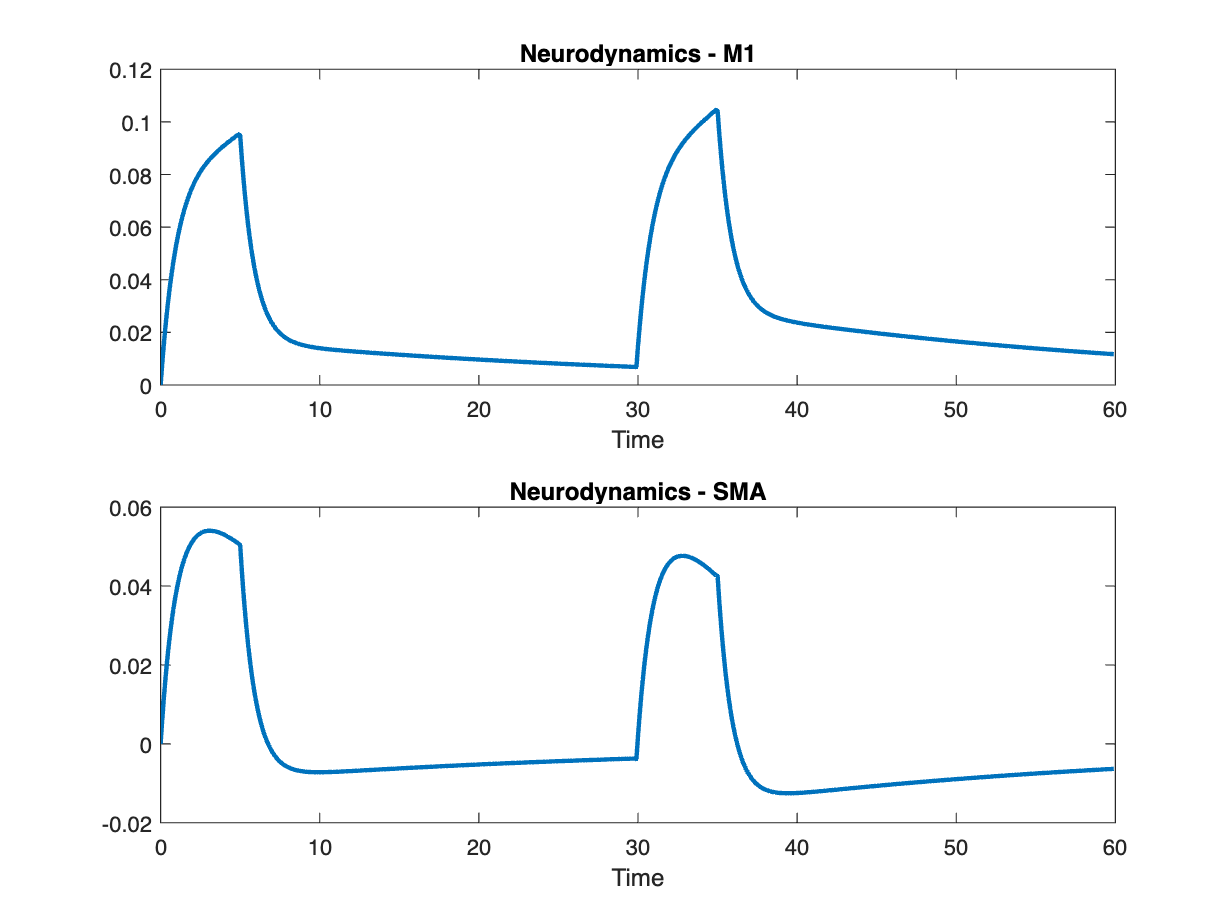

Zm1  = Z(1,:);
Zsma = Z(2,:);  
figure
ax1 = subplot(2,1,1); % top subplot
plot(ax1,timestamps,Zm1,'LineWidth',2);
title(ax1,'Neurodynamics - M1');
xlabel(ax1,'Time');

ax2 = subplot(2,1,2); % bottom subplot
plot(ax2,timestamps,Zsma,'LineWidth',2);
title(ax2,'Neurodynamics - SMA');
xlabel(ax2,'Time');

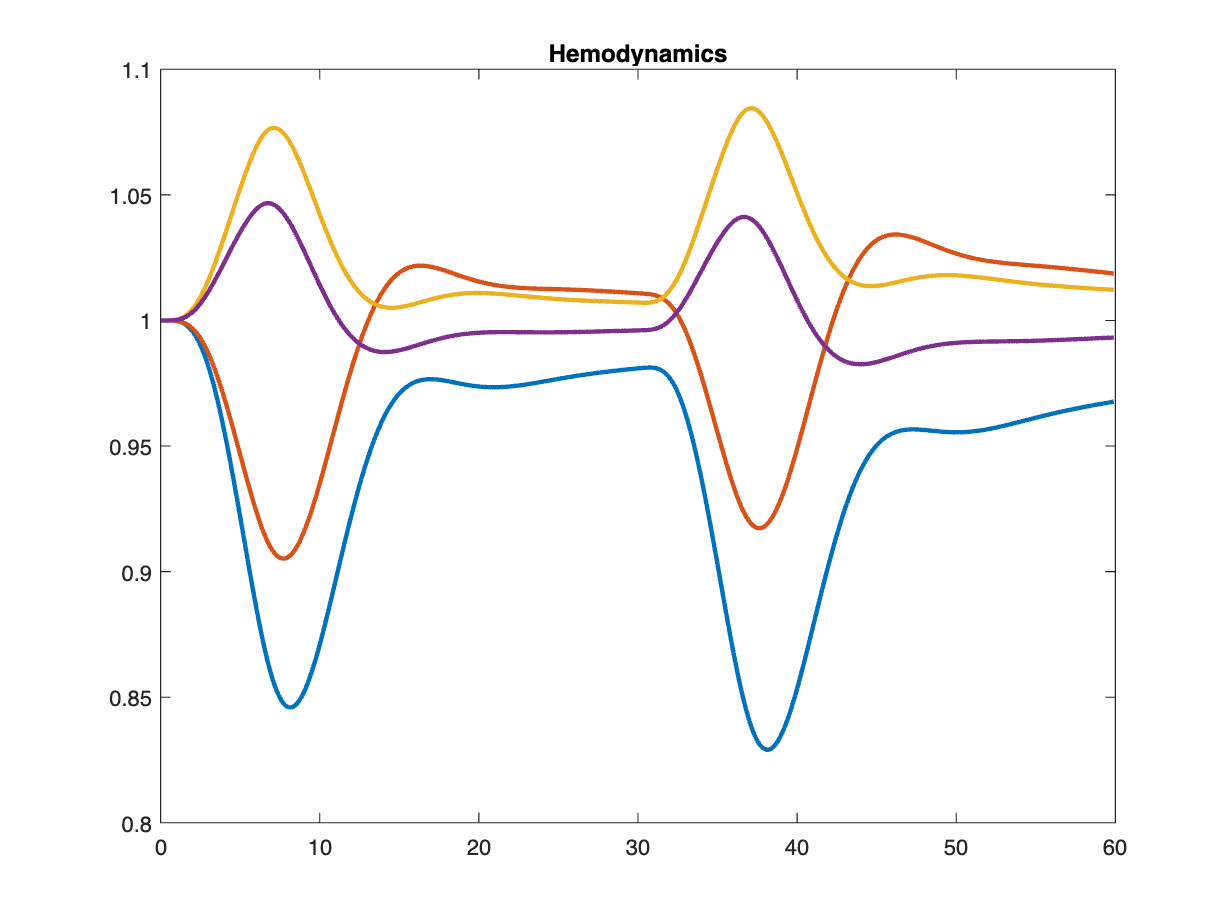


Hemodynamics = zeros(4, length(timestamps));

Hemodynamics(1,:) = qj(1,:);
Hemodynamics(2,:) = qj(2,:);

Hemodynamics(3,:) = pj(1,:);
Hemodynamics(4,:) = pj(2,:);
figure
plot(timestamps,Hemodynamics,'LineWidth',2);
title('Hemodynamics')

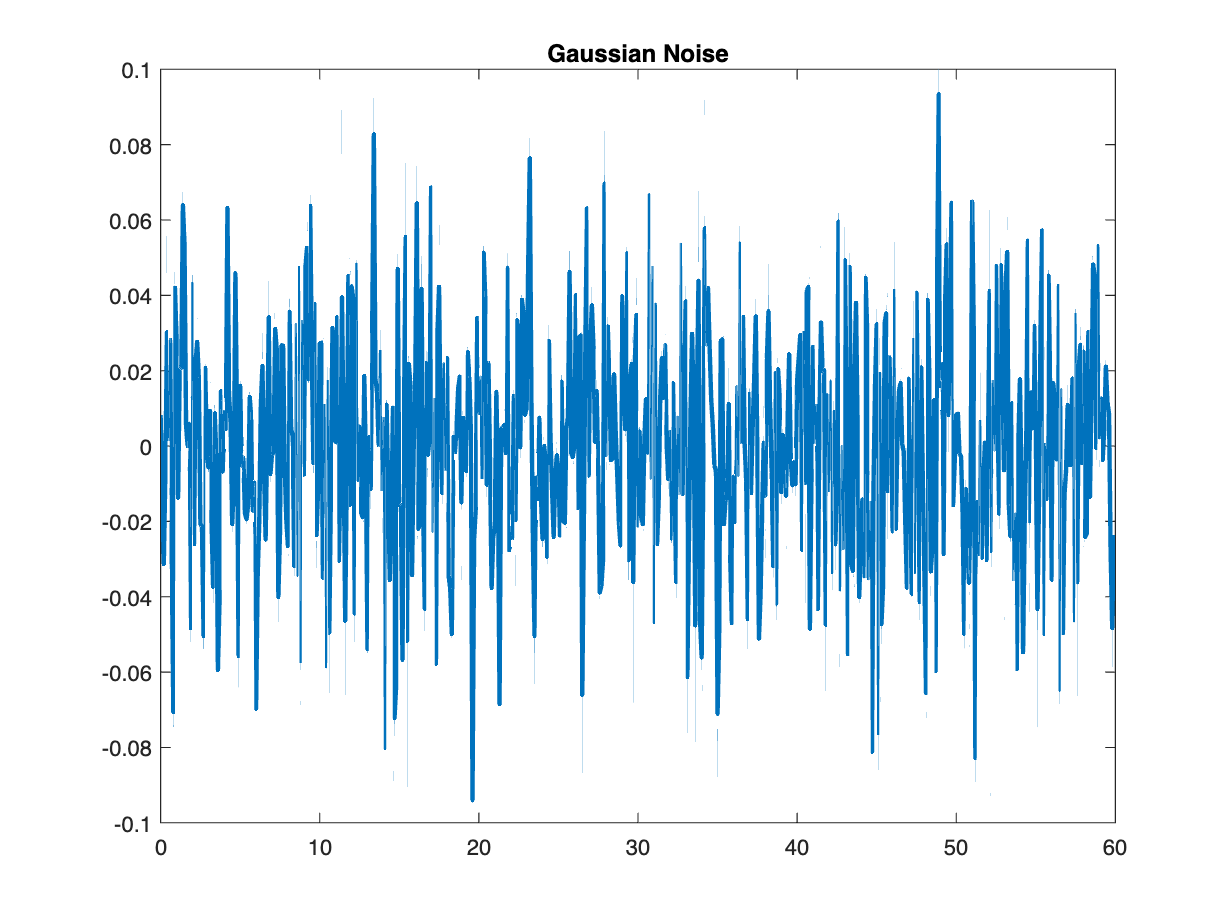

HemoMin = min(Hemodynamics);
HemoMin = min(HemoMin);
HemoMax = max(Hemodynamics);
HemoMax = max(HemoMax);

HemoRange =  HemoMax - HemoMin;

%Adding Gaussian Nosie
%Using normrnd based on timestamps and HemoRange
GaussianNoise = normrnd(0,0.3, size(timestamps));
GaussianNoise = GaussianNoise .* 0.1;
figure
plot(timestamps,GaussianNoise,'LineWidth',2);
title('Gaussian Noise')

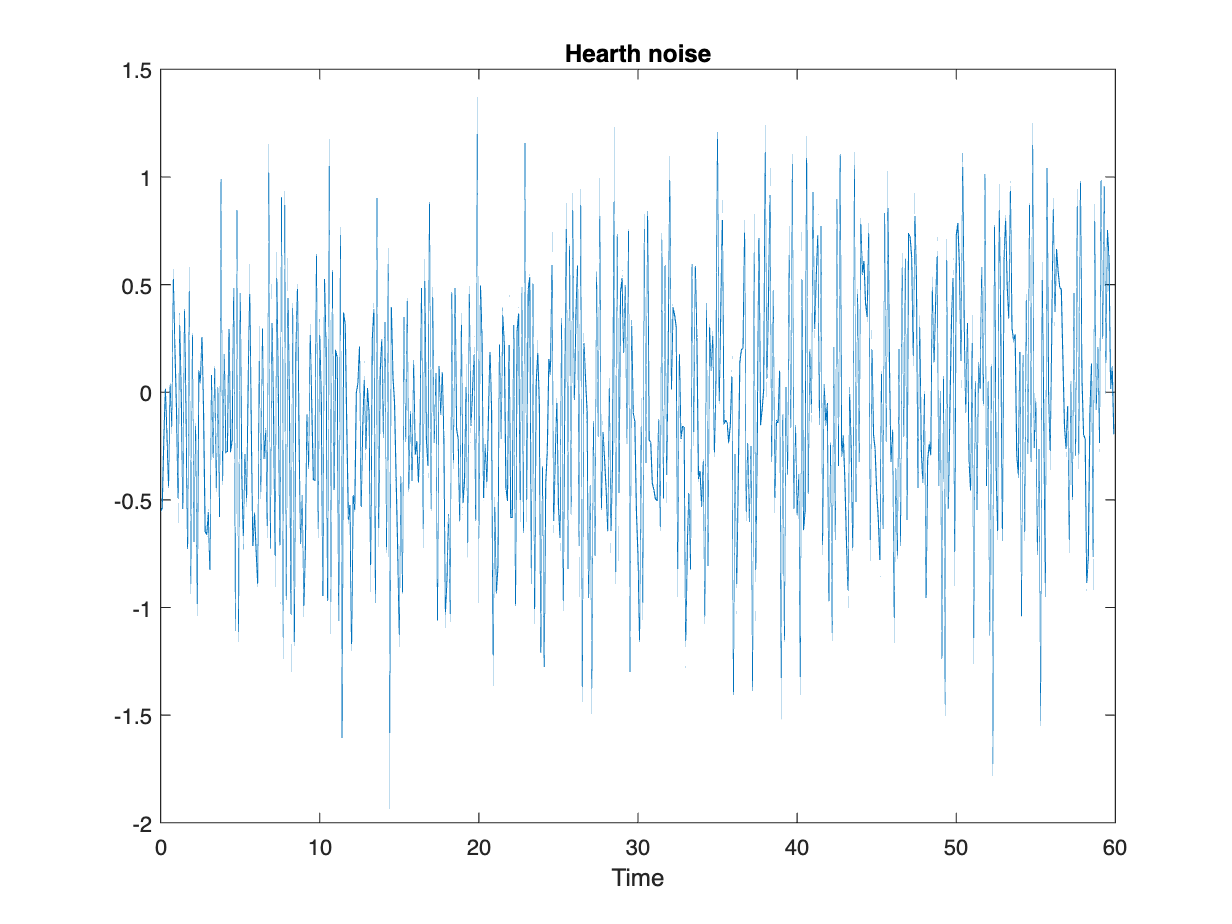

%Testing hearth rate
%FreqMean 1.08; FreqSD 0.16;
HearthNoise = Neurofeedback_PhysiologicalNoise_v2(1.08, 0.16, step, timestamps);
HearthNoise = HearthNoise(:,:).* 0.1;
%NOTA: SE ESTÁN GRAFICANDO LAS 4 SEÑALES( 2 POR REGION) Y NO TIENE LA
%HEMODINÁMICA SOLO ES EL RUIDO
figure
plot(timestamps,HearthNoise);
title('Hearth noise');
xlabel('Time');

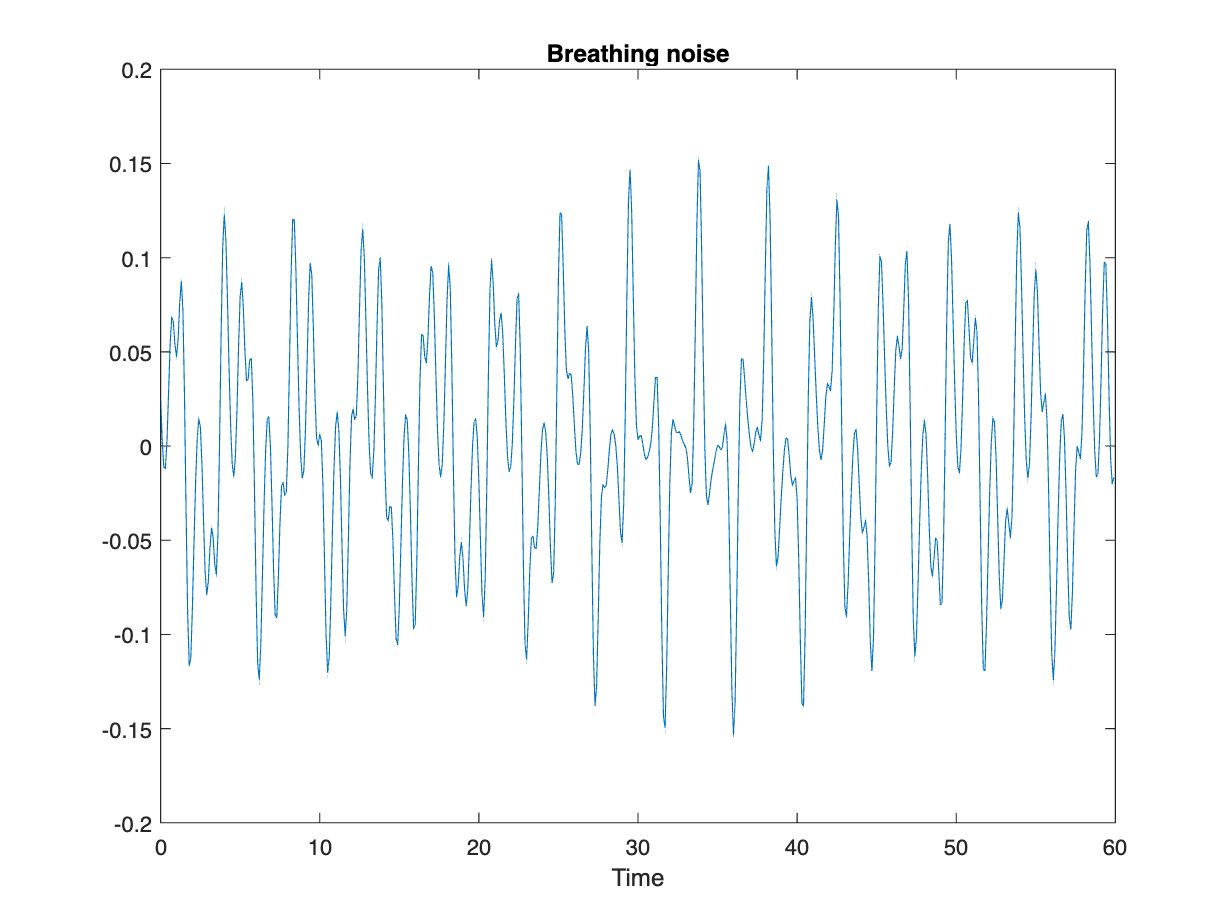

%Testing Breathing rate
%FreqMean 0.22; FreqSD 0.07;
BreathingNoise = Neurofeedback_PhysiologicalNoise_v2(0.22, 0.07, step, timestamps);
BreathingNoise = BreathingNoise .* 0.1;

figure
plot(timestamps,BreathingNoise);
title('Breathing noise');
xlabel('Time');

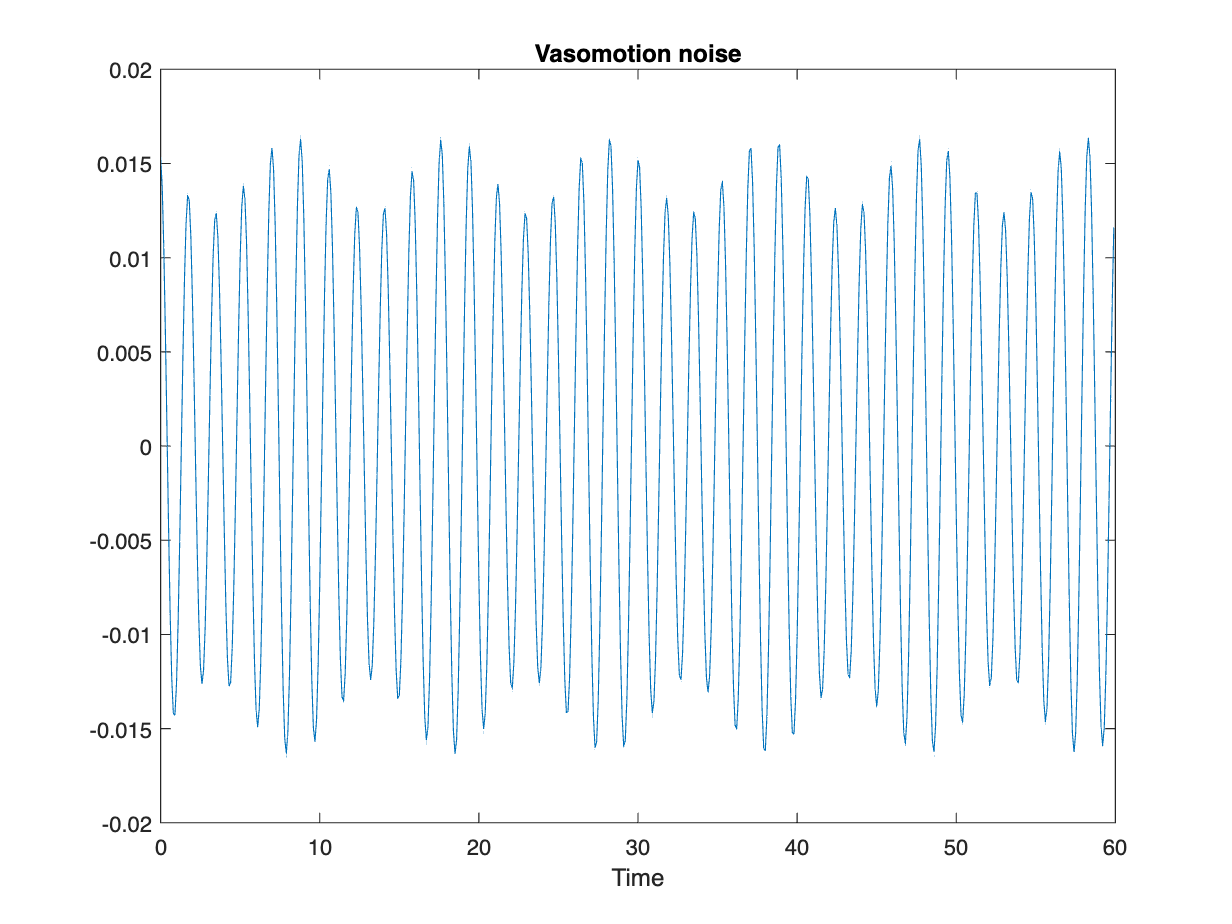

%Testing Vasomotion 
%FreqMean 0.082; FreqSD 0.016;
VasomotionNoise = Neurofeedback_PhysiologicalNoise_v2(0.082, 0.016, step, timestamps);
VasomotionNoise = VasomotionNoise .* 0.1;
%CHECK
figure
plot(timestamps,VasomotionNoise);
title('Vasomotion noise');
xlabel('Time');

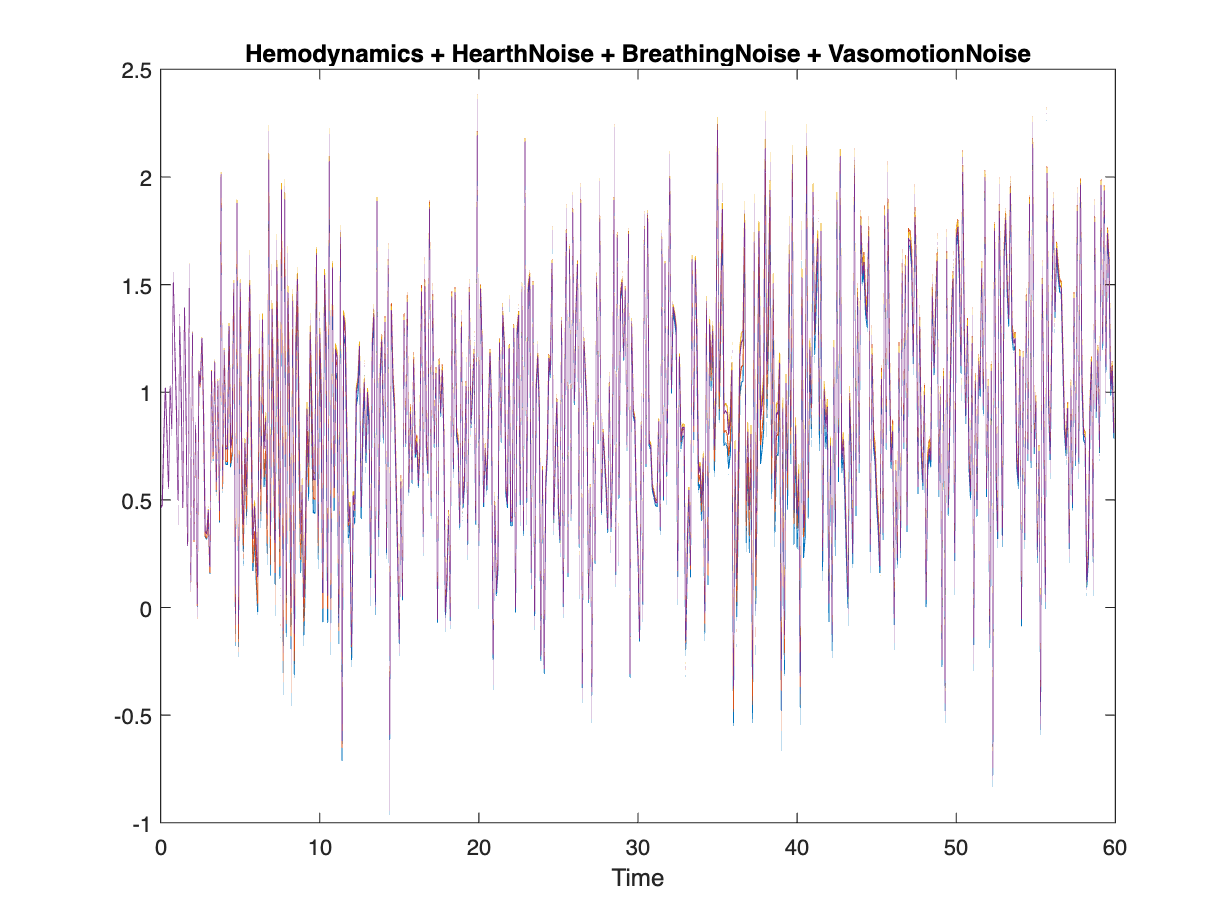

%Noises incorporation
Hemodynamics(:,:) = Hemodynamics(:,:) + HearthNoise(:,:) + VasomotionNoise(:,:); 

figure 
plot(timestamps, Hemodynamics)
title('Hemodynamics + HearthNoise + BreathingNoise + VasomotionNoise');
xlabel('Time');

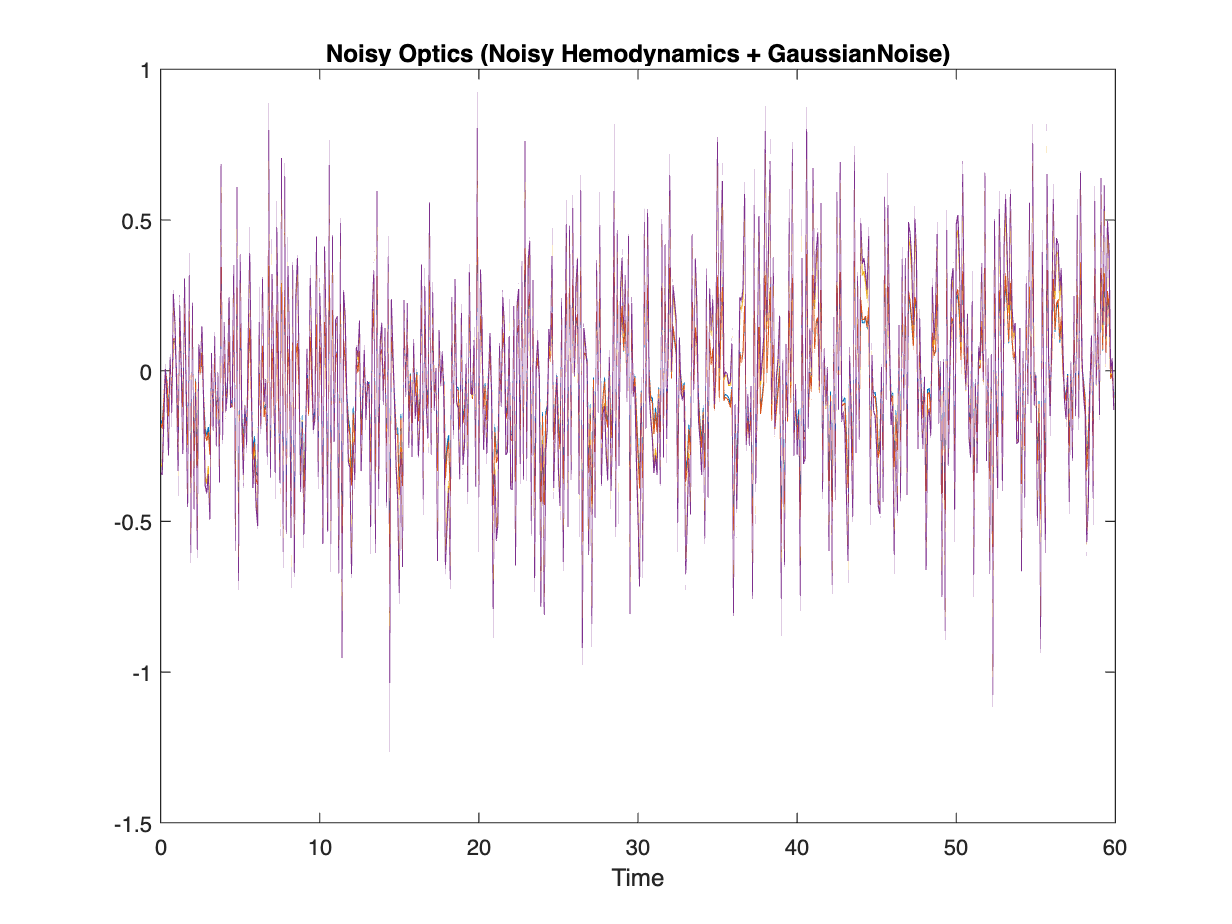

%Optics with Hemodynamics + Gaussian Noise
OpticsPj = zeros(2, length(timestamps));
OpticsPj(1, :) = Hemodynamics(3, :);
OpticsPj(2, :) = Hemodynamics(4, :);

OpticsQj = zeros(2, length(timestamps));
OpticsQj(1, :) = Hemodynamics(1, :);
OpticsQj(2, :) = Hemodynamics(2, :);

[Y] = BilinearModel_Optics_Naive_v2(OpticsPj, OpticsQj,U_stimulus,A);
figure
Y = Y + GaussianNoise;
plot(timestamps,Y);
title('Noisy Optics (Noisy Hemodynamics + GaussianNoise)');
xlabel('Time');

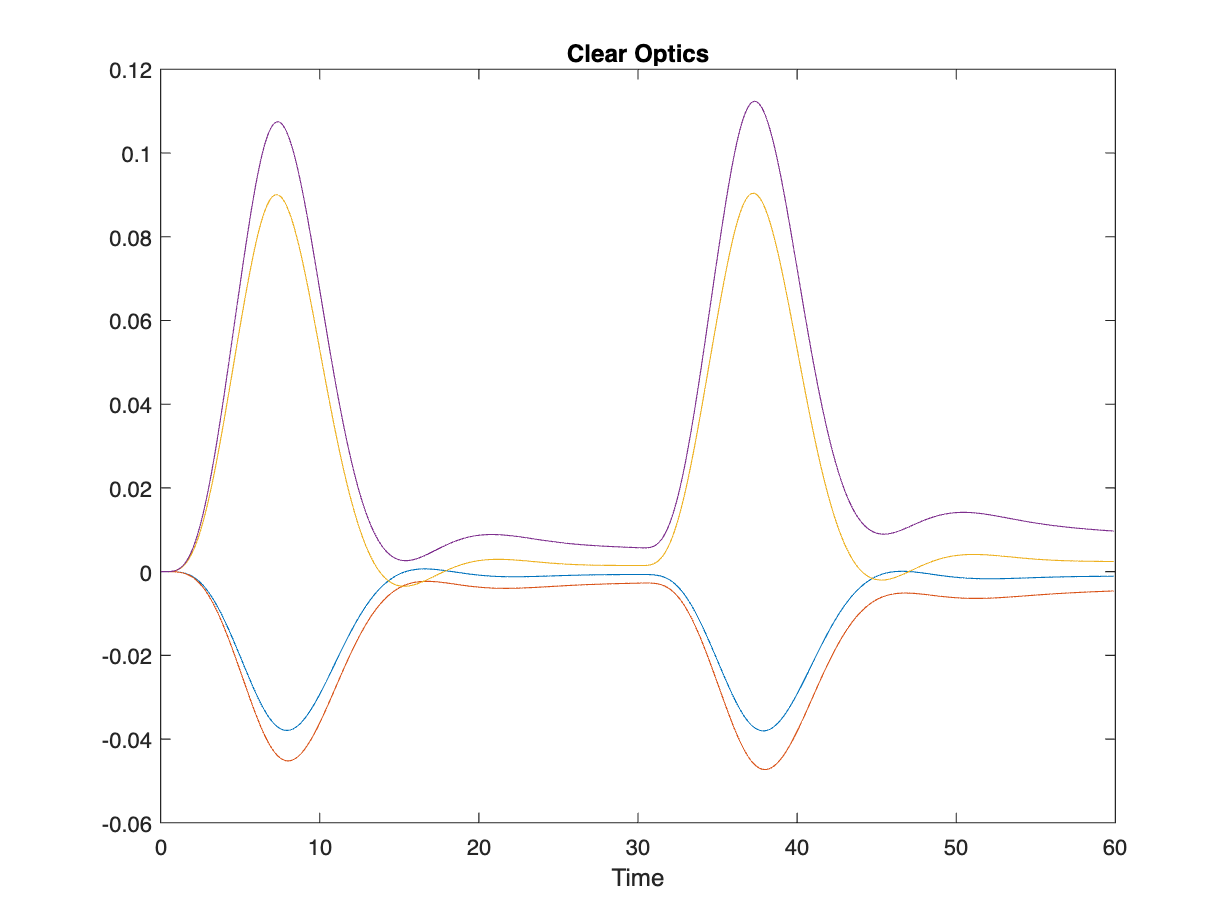

[Y_s] = BilinearModel_Optics_Naive_v2(pj, qj,U_stimulus,A);
figure
plot(timestamps,Y_s);
title('Clear Optics');
xlabel('Time');